TSL control

clear; 
% Laser
dllPath = fullfile(pwd, 'Santec_FTDI.dll');
asmInfo = NET.addAssembly(dllPath); pause(1);

TSL = Santec_FTDI.FTD2xx_helper('20060036');
pause(1);
TSL.Query('*IDN?')

ans = NR


% connect to agilent 8164B
delete(instrfindall);
agi = start_laser(); % note: this is a legacy function name for the 8164b

Agilent Technologies,8164B,DE48202184,V5.24(71730)



 % Turn on laser
TSL.Query('LO')

ans = 000.000


 % Turn off laser
TSL.Query('LF')

ans = 0000.0050


 % Shutter on
TSL.Query('SC')

ans = 010.000


 % Shutter off
TSL.Query('SO')

ans = 001.000


 % Set wavelength
temp_wav = 1550.185

temp_wav = 1.5502e+03

TSL.Query(strcat('WA',num2str(temp_wav,'%.4f'))); pause(0.05)
clear('temp_wav')

 % Set power
temp_pwr = 1

temp_pwr = 1

TSL.Query(strcat('LP',num2str(temp_pwr,'%.2f'))); pause(0.05)
clear('temp_pwr')
% Laser Power in mW
TSL.Query('LP')

ans = 000.000


wvStart = 1480 % nm

wvStart = 1480

wvEnd = 1630 % nm

wvEnd = 1630

wvRes = 0.01 % nm

wvRes = 0.0100

wvSpeed = 20 % nm/s

wvSpeed = 20

 
agilent_detector_range = -60; % dBm, multiple of 10 from -60 to 10

% Scan script settings
% TSL settings
TSL.Write('*CLS'); pause(0.1)
TSL.Write('*RST'); pause(0.1)
TSL.Query('SM 1'); % Sweep Mode; 1-continous one way, 2-continous two ways, 3- step one way
pause(0.1); TSL.Query('SZ 1'); % Number of sweeps
pause(0.1); TSL.Query('TM 2'); % Trigger behaviour; 1-Stop, 2-Start, 3-Step
pause(0.1); TSL.Query(char(sprintf('SS %.4f', wvStart))); % Start wavelength (nm)
pause(0.1); TSL.Query(sprintf('SE %.4f', wvEnd));
pause(0.1); TSL.Query(sprintf('SN %.1f',wvSpeed)); % Continous sweep speed (nm/s); [0.5:0.1:100]
pause(0.1); %TSL.Query(sprintf('TW %.4f',dummy_wvRes)); %0.0015 Trigger step (nm); [0.0001:0.0001:160] <1kHz
%TSL.Query("WA"+num2str(temp_wvStart,'%.4f')); pause(0.3)
wvs = wvStart:wvRes:wvEnd;
scanTime = ceil((wvEnd-wvStart)/wvSpeed)

scanTime = 8


% agilent setup
agilent_num_points = length(wvs);
agilent_sample_period = wvRes/wvSpeed

agilent_sample_period = 5.0000e-04

% open loop triggering only from first santec trigger, then agilent
% simply collects values at a rate according to sweep speed
% the accuracy of this seems fine, and it allows very rapid sweeps (10 kHz)
agilent_setup_logging(agi, agilent_num_points, ...
    agilent_sample_period);
clear('temp_wvEnd','temp_wvStart','temp_wvSpeed','temp_wvRes')

% this function re-arms trigger for repeated measurements (logging)
agilent_arm_logging(agi, agilent_detector_range);
TSL.Query('SG')

ans = 020.000


max_wait_time = scanTime+5; % time to wait for agilent before timing out
laser.Timeout = max_wait_time;
loggingSuccessful = agilent_wait_for_logging(agi, max_wait_time);

Agilent power meter logging in progress...
.Agilent complete!


if(loggingSuccessful)
    [channel1, channel2] = agilent_get_logging_result(agi);
    agilent_reset_triggers(agi);
else
    warning("Logging did not finish in alloted time.");
end

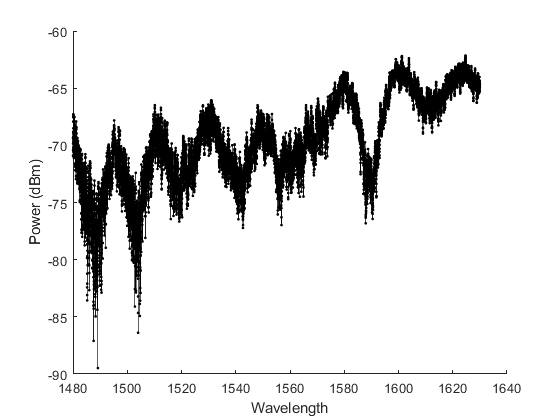

figure; hold on;
plot(wvs, 10*log10(abs(channel1)) + 30, 'k.-');
%plot(wvs, 10*log10(abs(channel2)) + 30);
hold off;
xlabel("Wavelength");
ylabel("Power (dBm)");

% save result
[output_filename, output_path] = uiputfile('*', 'Select location to save data:');
if(output_filename)
    %save(strcat(output_path,output_filename), 'wvs', 'channel1', 'channel2');
    save(strcat(output_path,output_filename), 'wvs', 'channel1');
else
    disp("File save cancelled");
end

File save cancelled


 % Disconnect
 
% if(exist('TSL','var'))
%     TSL.CloseUsbConnection(); % Laser
%     clear('TSL')
% end